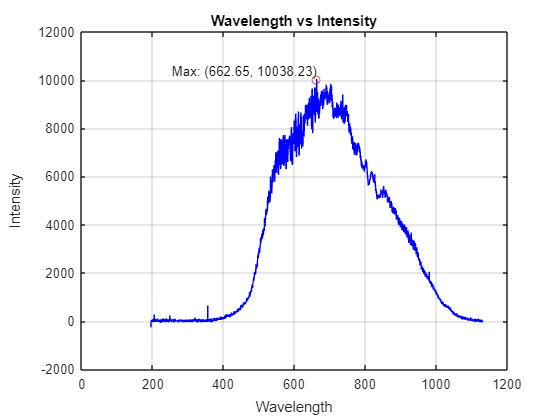

% Define the file name
filename =  "C:\Users\jerub\Desktop\ECCE\Courses-Modules\Msc Project\11-dshaped fiber (without jacket)\with 0.9%nacl_HR4C58731_16-51-06-532.txt";
data = readmatrix(filename);

% Extract the wavelength and intensity columns
wavelength = data(:, 1);
intensity = data(:, 2);

% Find the maximum intensity and the corresponding wavelength
[max_intensity, max_index] = max(intensity);
max_wavelength = wavelength(max_index);

% Plot the data
figure;
plot(wavelength, intensity, 'b-');
hold on;
plot(max_wavelength, max_intensity, 'ro'); % Mark the maximum point
xlabel('Wavelength');
ylabel('Intensity');
title('Wavelength vs Intensity');
grid on;

% Annotate the maximum point
text(max_wavelength, max_intensity, sprintf('Max: (%.2f, %.2f)', max_wavelength, max_intensity), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');


% Display the maximum wavelength and intensity
fprintf('Maximum Intensity: %.2f at Wavelength: %.2f\n', max_intensity, max_wavelength);

Maximum Intensity: 10038.23 at Wavelength: 662.65
